## Lecture 3

Introducing multirate systems

x = [0, 1, 2, -1];
xup2 = upsample_by_adding_zeros(x, 2);

h = [1, 1]

h =      1     1


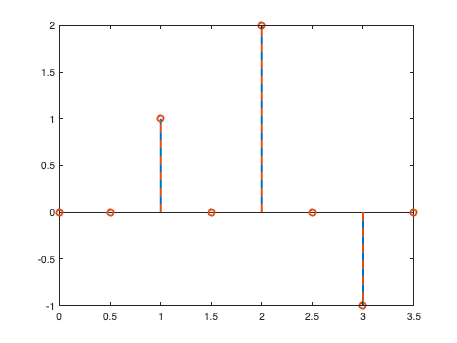


figure(1); clf;
stem(0:1:length(x)-1, x, '-', 'LineWidth', 2); hold on
stem(0:0.5:length(x)-0.5, xup2, '--', 'LineWidth', 2)

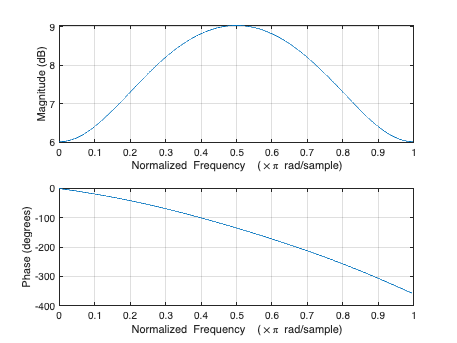


figure(2); clf;
freqz(x); hold on

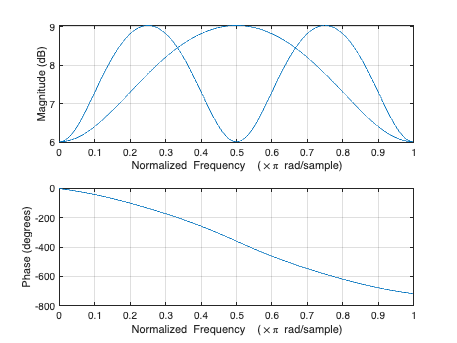

freqz(xup2)

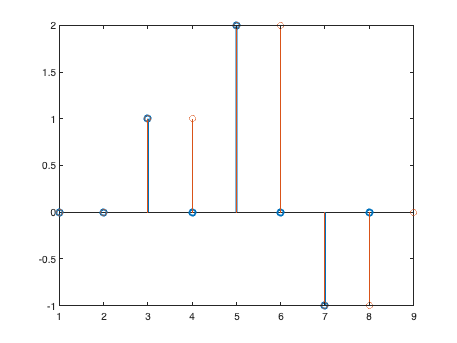


figure(3); clf;
stem(xup2, 'LineWidth', 2); hold on
stem(conv(xup2, h))

## Lecture 4

Designing interpolation filters

x = [1, 2, -1] % we just have a delay compared to lec3

x =      1     2    -1


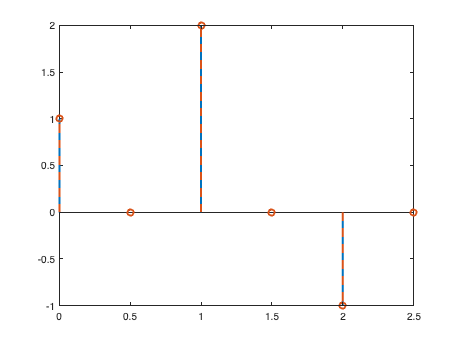

xup2 = upsample_by_adding_zeros(x, 2);

figure(1); clf;
stem(0:1:length(x)-1, x, '-', 'LineWidth', 2); hold on
stem(0:0.5:length(x)-0.5, xup2, '--', 'LineWidth', 2)

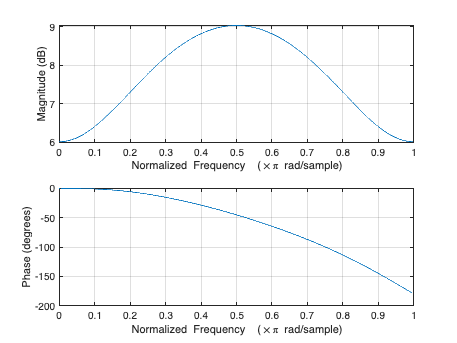


figure(2); clf;
freqz(x); hold on

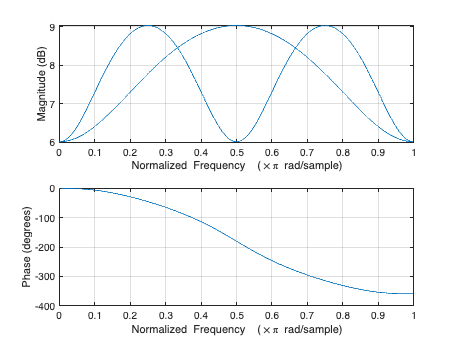

freqz(xup2)

For a linear interpolation filter, we can think of:


$$y\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
x\left\lbrack n\right\rbrack , & \mathrm{if}\;n\;\mathrm{is}\;\mathrm{even}\\
\frac{x\left\lbrack n-1\right\rbrack +x\left\lbrack n+1\right\rbrack }{2}, & \mathrm{if}\;n\;\mathrm{is}\;\mathrm{odd}
\end{array}\right.$$


These can just be combined into one function as every other sample is 0:


$$y[n]=x[n]+\frac{x[n-1]+x[n+1]}{2} \\
= \frac{1}{2}x[n-1] + x[n]+\frac{1}{2}x[n+1]$$


z = tf('z', 1);
h = 0.5*z + 1 + 0.5*z^(-1);
figure(2); clf;
freqresp(h);

function [xupn] = upsample_by_adding_zeros(x, n)
    xupn = zeros(1, length(x)*n);
    for i = 1:length(x)
        xupn(1, 1 + n*(i-1)) = x(i);
    end
end